## Variable Initializations

Gamma_barldb= [8:2:24];
Gamma_barldb1=Gamma_barldb/10;
Gamma_barl=10.^Gamma_barldb1;
N=5;
L=2;



## Generating fading coefficients

Npt=100000

Npt = 100000


for i=1:L
    for j=1:Npt
        alpha= raylrnd(1/sqrt(2),1,N);
        beta= raylrnd(1/sqrt(2),1,N);
    
        Al_Square(i,j)= dot(alpha,beta)^2;
        
    end
    
end

Al_Square_Mean= mean(Al_Square);


count1=zeros(length(Gamma_barl),1)

count1 =      0
     0
     0
     0
     0
     0
     0
     0
     0


for k=1:length(Gamma_barl)
    Gamma_l=Gamma_barl(k)*Al_Square
        for j=1:Npt
            if Gamma_l(1,j)<100
               count1(k)=count1(k)+1; 
            end
            
        end
end

Gamma_l = 	1.0e+03 *

    0.0414    0.0778    0.0943    0.1052    0.0806    0.0307    0.1147    0.1439    0.0124    0.2874    0.0667    0.0296    0.0795    0.0554    0.0258    0.0568    0.1763    0.0509    0.0593    0.1187    0.0406    0.1294    0.0708    0.0230    0.1566    0.2170    0.1320    0.0382    0.0741    0.1114    0.0397    0.0546    0.0653    0.0998    0.0425    0.1580    0.1364    0.1221    0.2173    0.0309    0.2747    0.1285    0.1008    0.0767    0.1113    0.0135    0.0744    0.0418    0.0514    0.0682
    0.1823    0.1276    0.0355    0.1268    0.1557    0.2193    0.0602    0.0931    0.1356    0.0902    0.1195    0.1969    0.0611    0.0148    0.1071    0.0931    0.0264    0.1004    0.0711    0.1118    0.0512    0.0630    0.0363    0.0800    0.2123    0.0325    0.0941    0.2358    0.0643    0.1548    0.0150    0.1353    0.0500    0.3342    0.1144    0.1283    0.0744    0.0609    0.0198    0.0990    0.1351    0.1367    0.3747    0.0294    0.0412    0.3539    0.0239    0.1

Gamma_l = 	1.0e+03 *

    0.0655    0.1232    0.1494    0.1668    0.1278    0.0486    0.1817    0.2281    0.0196    0.4556    0.1057    0.0469    0.1260    0.0878    0.0409    0.0900    0.2795    0.0807    0.0940    0.1882    0.0644    0.2052    0.1123    0.0365    0.2482    0.3440    0.2093    0.0605    0.1174    0.1766    0.0629    0.0865    0.1035    0.1581    0.0673    0.2504    0.2162    0.1935    0.3444    0.0489    0.4353    0.2036    0.1598    0.1215    0.1764    0.0214    0.1179    0.0662    0.0815    0.1081
    0.2889    0.2022    0.0563    0.2010    0.2468    0.3475    0.0955    0.1476    0.2150    0.1429    0.1894    0.3120    0.0968    0.0235    0.1697    0.1476    0.0418    0.1591    0.1127    0.1773    0.0812    0.0999    0.0575    0.1267    0.3365    0.0514    0.1491    0.3737    0.1019    0.2453    0.0238    0.2144    0.0792    0.5297    0.1813    0.2033    0.1178    0.0966    0.0314    0.1569    0.2141    0.2166    0.5939    0.0466    0.0653    0.5609    0.0379    0.1

Gamma_l = 	1.0e+03 *

    0.1039    0.1953    0.2367    0.2643    0.2025    0.0770    0.2880    0.3615    0.0311    0.7220    0.1675    0.0743    0.1996    0.1391    0.0648    0.1426    0.4429    0.1278    0.1490    0.2983    0.1020    0.3251    0.1780    0.0578    0.3934    0.5452    0.3316    0.0959    0.1861    0.2799    0.0997    0.1372    0.1641    0.2506    0.1066    0.3969    0.3426    0.3066    0.5459    0.0776    0.6900    0.3227    0.2533    0.1926    0.2796    0.0339    0.1869    0.1050    0.1291    0.1713
    0.4579    0.3205    0.0893    0.3186    0.3912    0.5508    0.1513    0.2339    0.3407    0.2265    0.3002    0.4945    0.1534    0.0372    0.2689    0.2339    0.0663    0.2522    0.1787    0.2809    0.1287    0.1583    0.0911    0.2008    0.5332    0.0815    0.2363    0.5923    0.1615    0.3888    0.0377    0.3399    0.1255    0.8395    0.2873    0.3223    0.1868    0.1531    0.0498    0.2487    0.3393    0.3433    0.9413    0.0738    0.1035    0.8890    0.0601    0.2

Gamma_l = 	1.0e+03 *

    0.1646    0.3096    0.3752    0.4189    0.3210    0.1221    0.4565    0.5730    0.0493    1.1443    0.2655    0.1178    0.3164    0.2205    0.1027    0.2260    0.7020    0.2026    0.2361    0.4727    0.1617    0.5153    0.2820    0.0917    0.6236    0.8640    0.5256    0.1519    0.2949    0.4436    0.1580    0.2174    0.2601    0.3971    0.1690    0.6290    0.5430    0.4860    0.8652    0.1229    1.0935    0.5114    0.4015    0.3053    0.4432    0.0538    0.2962    0.1664    0.2046    0.2715
    0.7257    0.5079    0.1415    0.5049    0.6200    0.8730    0.2398    0.3708    0.5400    0.3590    0.4757    0.7837    0.2432    0.0589    0.4262    0.3706    0.1051    0.3998    0.2831    0.4453    0.2039    0.2508    0.1445    0.3183    0.8451    0.1292    0.3746    0.9388    0.2559    0.6162    0.0598    0.5387    0.1989    1.3305    0.4554    0.5108    0.2960    0.2426    0.0789    0.3942    0.5377    0.5442    1.4918    0.1170    0.1641    1.4089    0.0953    0.3

Gamma_l = 	1.0e+03 *

    0.2609    0.4906    0.5947    0.6640    0.5087    0.1935    0.7235    0.9082    0.0782    1.8137    0.4209    0.1867    0.5015    0.3495    0.1627    0.3582    1.1126    0.3211    0.3742    0.7492    0.2563    0.8167    0.4470    0.1453    0.9883    1.3694    0.8331    0.2408    0.4674    0.7030    0.2503    0.3445    0.4122    0.6294    0.2679    0.9968    0.8606    0.7702    1.3712    0.1948    1.7332    0.8105    0.6363    0.4838    0.7024    0.0852    0.4694    0.2637    0.3243    0.4303
    1.1501    0.8050    0.2243    0.8002    0.9827    1.3836    0.3801    0.5876    0.8558    0.5689    0.7540    1.2421    0.3854    0.0934    0.6756    0.5874    0.1665    0.6336    0.4488    0.7057    0.3232    0.3975    0.2290    0.5045    1.3394    0.2048    0.5937    1.4879    0.4056    0.9767    0.0948    0.8537    0.3152    2.1088    0.7217    0.8095    0.4692    0.3845    0.1251    0.6248    0.8522    0.8624    2.3644    0.1855    0.2601    2.2330    0.1510    0.6

Gamma_l = 	1.0e+04 *

    0.0414    0.0778    0.0943    0.1052    0.0806    0.0307    0.1147    0.1439    0.0124    0.2874    0.0667    0.0296    0.0795    0.0554    0.0258    0.0568    0.1763    0.0509    0.0593    0.1187    0.0406    0.1294    0.0708    0.0230    0.1566    0.2170    0.1320    0.0382    0.0741    0.1114    0.0397    0.0546    0.0653    0.0998    0.0425    0.1580    0.1364    0.1221    0.2173    0.0309    0.2747    0.1285    0.1008    0.0767    0.1113    0.0135    0.0744    0.0418    0.0514    0.0682
    0.1823    0.1276    0.0355    0.1268    0.1557    0.2193    0.0602    0.0931    0.1356    0.0902    0.1195    0.1969    0.0611    0.0148    0.1071    0.0931    0.0264    0.1004    0.0711    0.1118    0.0512    0.0630    0.0363    0.0800    0.2123    0.0325    0.0941    0.2358    0.0643    0.1548    0.0150    0.1353    0.0500    0.3342    0.1144    0.1283    0.0744    0.0609    0.0198    0.0990    0.1351    0.1367    0.3747    0.0294    0.0412    0.3539    0.0239    0.1

Gamma_l = 	1.0e+04 *

    0.0655    0.1232    0.1494    0.1668    0.1278    0.0486    0.1817    0.2281    0.0196    0.4556    0.1057    0.0469    0.1260    0.0878    0.0409    0.0900    0.2795    0.0807    0.0940    0.1882    0.0644    0.2052    0.1123    0.0365    0.2482    0.3440    0.2093    0.0605    0.1174    0.1766    0.0629    0.0865    0.1035    0.1581    0.0673    0.2504    0.2162    0.1935    0.3444    0.0489    0.4353    0.2036    0.1598    0.1215    0.1764    0.0214    0.1179    0.0662    0.0815    0.1081
    0.2889    0.2022    0.0563    0.2010    0.2468    0.3475    0.0955    0.1476    0.2150    0.1429    0.1894    0.3120    0.0968    0.0235    0.1697    0.1476    0.0418    0.1591    0.1127    0.1773    0.0812    0.0999    0.0575    0.1267    0.3365    0.0514    0.1491    0.3737    0.1019    0.2453    0.0238    0.2144    0.0792    0.5297    0.1813    0.2033    0.1178    0.0966    0.0314    0.1569    0.2141    0.2166    0.5939    0.0466    0.0653    0.5609    0.0379    0.1

Gamma_l = 	1.0e+04 *

    0.1039    0.1953    0.2367    0.2643    0.2025    0.0770    0.2880    0.3615    0.0311    0.7220    0.1675    0.0743    0.1996    0.1391    0.0648    0.1426    0.4429    0.1278    0.1490    0.2983    0.1020    0.3251    0.1780    0.0578    0.3934    0.5452    0.3316    0.0959    0.1861    0.2799    0.0997    0.1372    0.1641    0.2506    0.1066    0.3969    0.3426    0.3066    0.5459    0.0776    0.6900    0.3227    0.2533    0.1926    0.2796    0.0339    0.1869    0.1050    0.1291    0.1713
    0.4579    0.3205    0.0893    0.3186    0.3912    0.5508    0.1513    0.2339    0.3407    0.2265    0.3002    0.4945    0.1534    0.0372    0.2689    0.2339    0.0663    0.2522    0.1787    0.2809    0.1287    0.1583    0.0911    0.2008    0.5332    0.0815    0.2363    0.5923    0.1615    0.3888    0.0377    0.3399    0.1255    0.8395    0.2873    0.3223    0.1868    0.1531    0.0498    0.2487    0.3393    0.3433    0.9413    0.0738    0.1035    0.8890    0.0601    0.2

Gamma_l = 	1.0e+04 *

    0.1646    0.3096    0.3752    0.4189    0.3210    0.1221    0.4565    0.5730    0.0493    1.1443    0.2655    0.1178    0.3164    0.2205    0.1027    0.2260    0.7020    0.2026    0.2361    0.4727    0.1617    0.5153    0.2820    0.0917    0.6236    0.8640    0.5256    0.1519    0.2949    0.4436    0.1580    0.2174    0.2601    0.3971    0.1690    0.6290    0.5430    0.4860    0.8652    0.1229    1.0935    0.5114    0.4015    0.3053    0.4432    0.0538    0.2962    0.1664    0.2046    0.2715
    0.7257    0.5079    0.1415    0.5049    0.6200    0.8730    0.2398    0.3708    0.5400    0.3590    0.4757    0.7837    0.2432    0.0589    0.4262    0.3706    0.1051    0.3998    0.2831    0.4453    0.2039    0.2508    0.1445    0.3183    0.8451    0.1292    0.3746    0.9388    0.2559    0.6162    0.0598    0.5387    0.1989    1.3305    0.4554    0.5108    0.2960    0.2426    0.0789    0.3942    0.5377    0.5442    1.4918    0.1170    0.1641    1.4089    0.0953    0.3

    

count1

count1 =        56076
       31709
       14278
        5340
        1727
         485
         112
          26
           1


prob1=count1/Npt

prob1 =     0.5608
    0.3171
    0.1428
    0.0534
    0.0173
    0.0049
    0.0011
    0.0003
    0.0000







L=2;





count2=zeros(length(Gamma_barl),1)

count2 =      0
     0
     0
     0
     0
     0
     0
     0
     0


for k=1:length(Gamma_barl)
    Gamma_l=Gamma_barl(k)*Al_Square
    for j=1:Npt
        if Gamma_l(1,j)<100 && Gamma_l(2,j)<100
           count2(k)=count2(k)+1; 
        end
        
    end
end

Gamma_l = 	1.0e+03 *

    0.0414    0.0778    0.0943    0.1052    0.0806    0.0307    0.1147    0.1439    0.0124    0.2874    0.0667    0.0296    0.0795    0.0554    0.0258    0.0568    0.1763    0.0509    0.0593    0.1187    0.0406    0.1294    0.0708    0.0230    0.1566    0.2170    0.1320    0.0382    0.0741    0.1114    0.0397    0.0546    0.0653    0.0998    0.0425    0.1580    0.1364    0.1221    0.2173    0.0309    0.2747    0.1285    0.1008    0.0767    0.1113    0.0135    0.0744    0.0418    0.0514    0.0682
    0.1823    0.1276    0.0355    0.1268    0.1557    0.2193    0.0602    0.0931    0.1356    0.0902    0.1195    0.1969    0.0611    0.0148    0.1071    0.0931    0.0264    0.1004    0.0711    0.1118    0.0512    0.0630    0.0363    0.0800    0.2123    0.0325    0.0941    0.2358    0.0643    0.1548    0.0150    0.1353    0.0500    0.3342    0.1144    0.1283    0.0744    0.0609    0.0198    0.0990    0.1351    0.1367    0.3747    0.0294    0.0412    0.3539    0.0239    0.1

Gamma_l = 	1.0e+03 *

    0.0655    0.1232    0.1494    0.1668    0.1278    0.0486    0.1817    0.2281    0.0196    0.4556    0.1057    0.0469    0.1260    0.0878    0.0409    0.0900    0.2795    0.0807    0.0940    0.1882    0.0644    0.2052    0.1123    0.0365    0.2482    0.3440    0.2093    0.0605    0.1174    0.1766    0.0629    0.0865    0.1035    0.1581    0.0673    0.2504    0.2162    0.1935    0.3444    0.0489    0.4353    0.2036    0.1598    0.1215    0.1764    0.0214    0.1179    0.0662    0.0815    0.1081
    0.2889    0.2022    0.0563    0.2010    0.2468    0.3475    0.0955    0.1476    0.2150    0.1429    0.1894    0.3120    0.0968    0.0235    0.1697    0.1476    0.0418    0.1591    0.1127    0.1773    0.0812    0.0999    0.0575    0.1267    0.3365    0.0514    0.1491    0.3737    0.1019    0.2453    0.0238    0.2144    0.0792    0.5297    0.1813    0.2033    0.1178    0.0966    0.0314    0.1569    0.2141    0.2166    0.5939    0.0466    0.0653    0.5609    0.0379    0.1

Gamma_l = 	1.0e+03 *

    0.1039    0.1953    0.2367    0.2643    0.2025    0.0770    0.2880    0.3615    0.0311    0.7220    0.1675    0.0743    0.1996    0.1391    0.0648    0.1426    0.4429    0.1278    0.1490    0.2983    0.1020    0.3251    0.1780    0.0578    0.3934    0.5452    0.3316    0.0959    0.1861    0.2799    0.0997    0.1372    0.1641    0.2506    0.1066    0.3969    0.3426    0.3066    0.5459    0.0776    0.6900    0.3227    0.2533    0.1926    0.2796    0.0339    0.1869    0.1050    0.1291    0.1713
    0.4579    0.3205    0.0893    0.3186    0.3912    0.5508    0.1513    0.2339    0.3407    0.2265    0.3002    0.4945    0.1534    0.0372    0.2689    0.2339    0.0663    0.2522    0.1787    0.2809    0.1287    0.1583    0.0911    0.2008    0.5332    0.0815    0.2363    0.5923    0.1615    0.3888    0.0377    0.3399    0.1255    0.8395    0.2873    0.3223    0.1868    0.1531    0.0498    0.2487    0.3393    0.3433    0.9413    0.0738    0.1035    0.8890    0.0601    0.2

Gamma_l = 	1.0e+03 *

    0.1646    0.3096    0.3752    0.4189    0.3210    0.1221    0.4565    0.5730    0.0493    1.1443    0.2655    0.1178    0.3164    0.2205    0.1027    0.2260    0.7020    0.2026    0.2361    0.4727    0.1617    0.5153    0.2820    0.0917    0.6236    0.8640    0.5256    0.1519    0.2949    0.4436    0.1580    0.2174    0.2601    0.3971    0.1690    0.6290    0.5430    0.4860    0.8652    0.1229    1.0935    0.5114    0.4015    0.3053    0.4432    0.0538    0.2962    0.1664    0.2046    0.2715
    0.7257    0.5079    0.1415    0.5049    0.6200    0.8730    0.2398    0.3708    0.5400    0.3590    0.4757    0.7837    0.2432    0.0589    0.4262    0.3706    0.1051    0.3998    0.2831    0.4453    0.2039    0.2508    0.1445    0.3183    0.8451    0.1292    0.3746    0.9388    0.2559    0.6162    0.0598    0.5387    0.1989    1.3305    0.4554    0.5108    0.2960    0.2426    0.0789    0.3942    0.5377    0.5442    1.4918    0.1170    0.1641    1.4089    0.0953    0.3

Gamma_l = 	1.0e+03 *

    0.2609    0.4906    0.5947    0.6640    0.5087    0.1935    0.7235    0.9082    0.0782    1.8137    0.4209    0.1867    0.5015    0.3495    0.1627    0.3582    1.1126    0.3211    0.3742    0.7492    0.2563    0.8167    0.4470    0.1453    0.9883    1.3694    0.8331    0.2408    0.4674    0.7030    0.2503    0.3445    0.4122    0.6294    0.2679    0.9968    0.8606    0.7702    1.3712    0.1948    1.7332    0.8105    0.6363    0.4838    0.7024    0.0852    0.4694    0.2637    0.3243    0.4303
    1.1501    0.8050    0.2243    0.8002    0.9827    1.3836    0.3801    0.5876    0.8558    0.5689    0.7540    1.2421    0.3854    0.0934    0.6756    0.5874    0.1665    0.6336    0.4488    0.7057    0.3232    0.3975    0.2290    0.5045    1.3394    0.2048    0.5937    1.4879    0.4056    0.9767    0.0948    0.8537    0.3152    2.1088    0.7217    0.8095    0.4692    0.3845    0.1251    0.6248    0.8522    0.8624    2.3644    0.1855    0.2601    2.2330    0.1510    0.6

Gamma_l = 	1.0e+04 *

    0.0414    0.0778    0.0943    0.1052    0.0806    0.0307    0.1147    0.1439    0.0124    0.2874    0.0667    0.0296    0.0795    0.0554    0.0258    0.0568    0.1763    0.0509    0.0593    0.1187    0.0406    0.1294    0.0708    0.0230    0.1566    0.2170    0.1320    0.0382    0.0741    0.1114    0.0397    0.0546    0.0653    0.0998    0.0425    0.1580    0.1364    0.1221    0.2173    0.0309    0.2747    0.1285    0.1008    0.0767    0.1113    0.0135    0.0744    0.0418    0.0514    0.0682
    0.1823    0.1276    0.0355    0.1268    0.1557    0.2193    0.0602    0.0931    0.1356    0.0902    0.1195    0.1969    0.0611    0.0148    0.1071    0.0931    0.0264    0.1004    0.0711    0.1118    0.0512    0.0630    0.0363    0.0800    0.2123    0.0325    0.0941    0.2358    0.0643    0.1548    0.0150    0.1353    0.0500    0.3342    0.1144    0.1283    0.0744    0.0609    0.0198    0.0990    0.1351    0.1367    0.3747    0.0294    0.0412    0.3539    0.0239    0.1

Gamma_l = 	1.0e+04 *

    0.0655    0.1232    0.1494    0.1668    0.1278    0.0486    0.1817    0.2281    0.0196    0.4556    0.1057    0.0469    0.1260    0.0878    0.0409    0.0900    0.2795    0.0807    0.0940    0.1882    0.0644    0.2052    0.1123    0.0365    0.2482    0.3440    0.2093    0.0605    0.1174    0.1766    0.0629    0.0865    0.1035    0.1581    0.0673    0.2504    0.2162    0.1935    0.3444    0.0489    0.4353    0.2036    0.1598    0.1215    0.1764    0.0214    0.1179    0.0662    0.0815    0.1081
    0.2889    0.2022    0.0563    0.2010    0.2468    0.3475    0.0955    0.1476    0.2150    0.1429    0.1894    0.3120    0.0968    0.0235    0.1697    0.1476    0.0418    0.1591    0.1127    0.1773    0.0812    0.0999    0.0575    0.1267    0.3365    0.0514    0.1491    0.3737    0.1019    0.2453    0.0238    0.2144    0.0792    0.5297    0.1813    0.2033    0.1178    0.0966    0.0314    0.1569    0.2141    0.2166    0.5939    0.0466    0.0653    0.5609    0.0379    0.1

Gamma_l = 	1.0e+04 *

    0.1039    0.1953    0.2367    0.2643    0.2025    0.0770    0.2880    0.3615    0.0311    0.7220    0.1675    0.0743    0.1996    0.1391    0.0648    0.1426    0.4429    0.1278    0.1490    0.2983    0.1020    0.3251    0.1780    0.0578    0.3934    0.5452    0.3316    0.0959    0.1861    0.2799    0.0997    0.1372    0.1641    0.2506    0.1066    0.3969    0.3426    0.3066    0.5459    0.0776    0.6900    0.3227    0.2533    0.1926    0.2796    0.0339    0.1869    0.1050    0.1291    0.1713
    0.4579    0.3205    0.0893    0.3186    0.3912    0.5508    0.1513    0.2339    0.3407    0.2265    0.3002    0.4945    0.1534    0.0372    0.2689    0.2339    0.0663    0.2522    0.1787    0.2809    0.1287    0.1583    0.0911    0.2008    0.5332    0.0815    0.2363    0.5923    0.1615    0.3888    0.0377    0.3399    0.1255    0.8395    0.2873    0.3223    0.1868    0.1531    0.0498    0.2487    0.3393    0.3433    0.9413    0.0738    0.1035    0.8890    0.0601    0.2

Gamma_l = 	1.0e+04 *

    0.1646    0.3096    0.3752    0.4189    0.3210    0.1221    0.4565    0.5730    0.0493    1.1443    0.2655    0.1178    0.3164    0.2205    0.1027    0.2260    0.7020    0.2026    0.2361    0.4727    0.1617    0.5153    0.2820    0.0917    0.6236    0.8640    0.5256    0.1519    0.2949    0.4436    0.1580    0.2174    0.2601    0.3971    0.1690    0.6290    0.5430    0.4860    0.8652    0.1229    1.0935    0.5114    0.4015    0.3053    0.4432    0.0538    0.2962    0.1664    0.2046    0.2715
    0.7257    0.5079    0.1415    0.5049    0.6200    0.8730    0.2398    0.3708    0.5400    0.3590    0.4757    0.7837    0.2432    0.0589    0.4262    0.3706    0.1051    0.3998    0.2831    0.4453    0.2039    0.2508    0.1445    0.3183    0.8451    0.1292    0.3746    0.9388    0.2559    0.6162    0.0598    0.5387    0.1989    1.3305    0.4554    0.5108    0.2960    0.2426    0.0789    0.3942    0.5377    0.5442    1.4918    0.1170    0.1641    1.4089    0.0953    0.3

    
count2

count2 =        31531
       10054
        2026
         285
          26
           1
           0
           0
           0


prob2=count2/Npt

prob2 =     0.3153
    0.1005
    0.0203
    0.0029
    0.0003
    0.0000
         0
         0
         0


### **Plots**

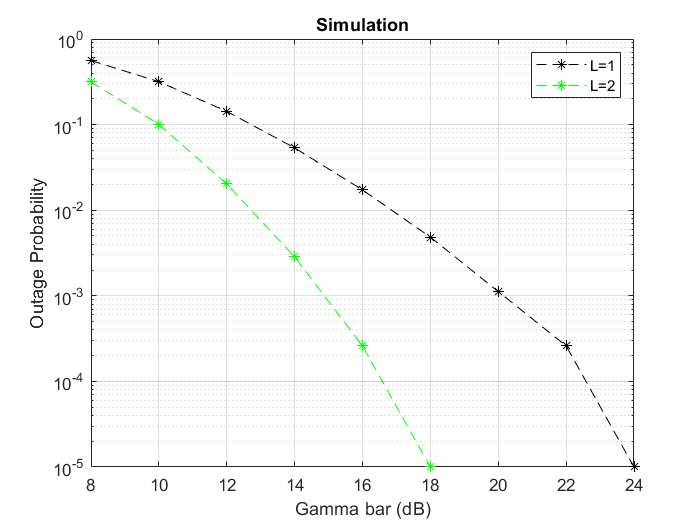

semilogy(Gamma_barldb,prob1,'k--*','MarkerFaceColor','auto');grid on;hold on;


semilogy(Gamma_barldb,prob2,'g--*','MarkerFaceColor','auto');grid on;hold on;

legend("L=1","L=2")
xlabel("Gamma bar (dB)")
ylabel("Outage Probability")
title("Simulation");